oldpath = path;
path(oldpath,'\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\pictures_of_calf\main_data\2018_07_10')

## 画像データをトリミングする際の画質劣化対策

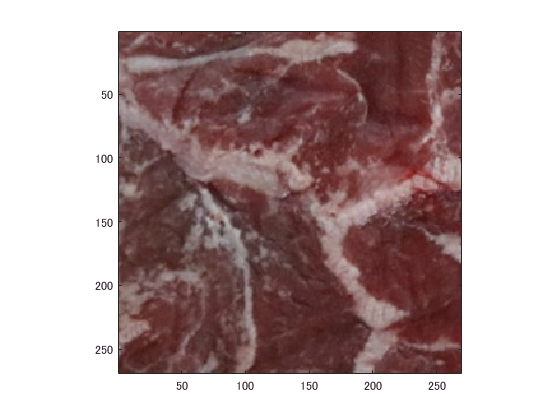

%東京芝浦臓器から納入された脛肉一帯からヒラメ筋に該当する箇所を正方領域40mmx40mmで抽出した画像データを読み込む
A = imread('2018_07_10_4x4cm^2_soleus.jpg');
%画像データを表示する
image(A)
axis tight
axis equal

size_A = size(A)

size_A =    269   269     3


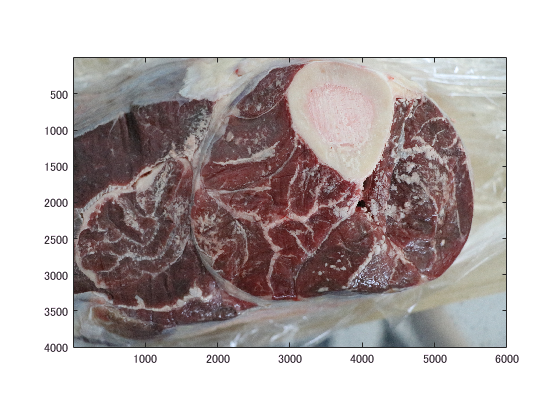

%このトリミングはパワーポイント上で行われた．一般にトリミングをすることで画質が下がる
%このことを確かめるために元の画像のサイズを確認する
A_raw = imread('IMG_2918.jpg');
image(A_raw)
axis tight
axis equal

size_A_raw = size(A_raw)

size_A_raw =         4000        6000           3


生データからのデータがそのまま保持されていれば800 x 800 pixel程度はあるはずだが，250 x 250 pixel程度になってしまった．

これを防ぐために"buff"というフリーソフトを使った．

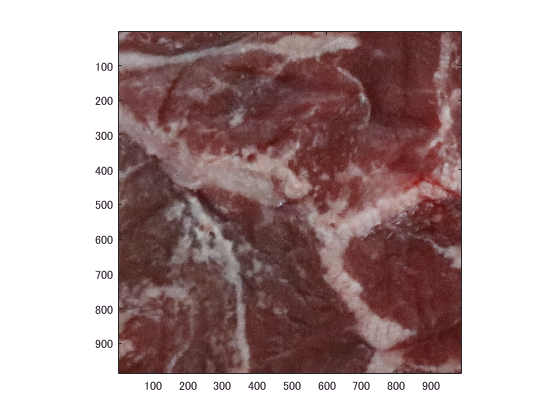

B = imread('2018_07_10_4x4cm^2_soleus_2.jpg');
image(B)
axis tight
axis equal

size_B = size(B)

size_B =    988   988     3


たしかに画質を保持できた

## 大津の二値化

大津の二値化によってEMCL領域とそれ以外の領域を示すように処理する

%RGB イメージをグレースケールに変換
gray_B = rgb2gray(B);
imshow(I_B)

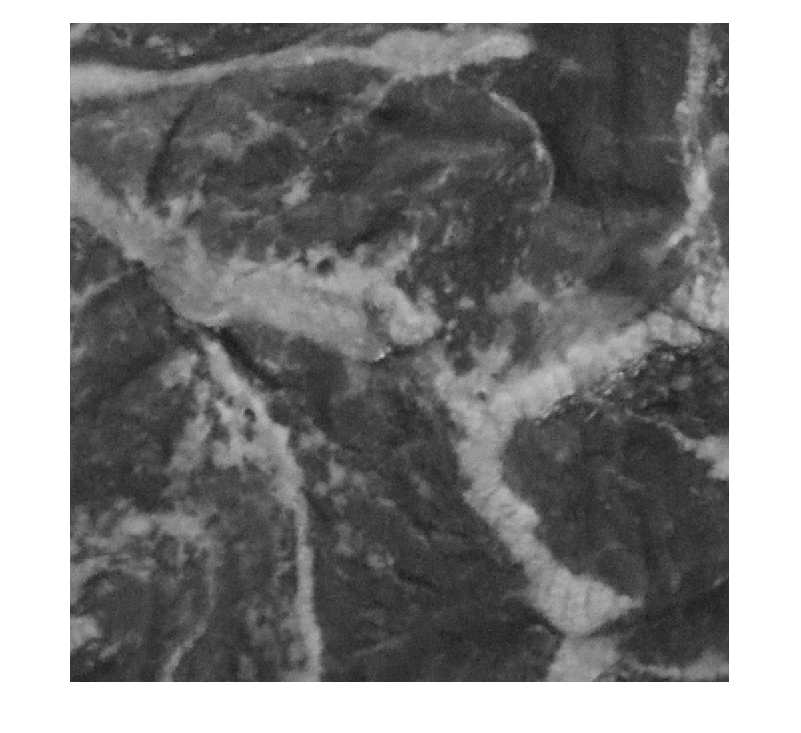

axis tight
axis equal

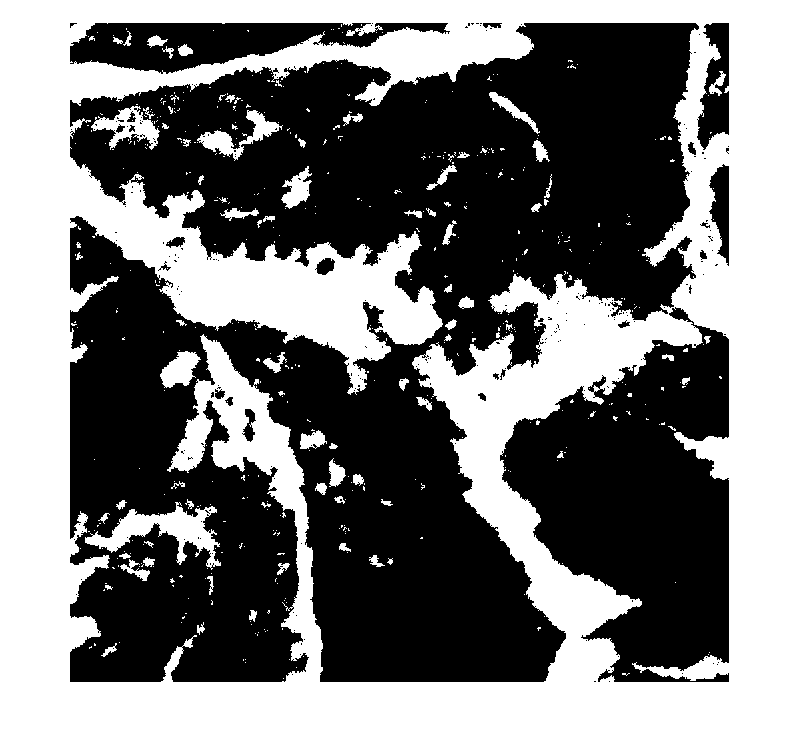

colormap gray
%大津の二値化をかける
BW_B = imbinarize(I_B);
BW_B_show = imshow(BW_B);

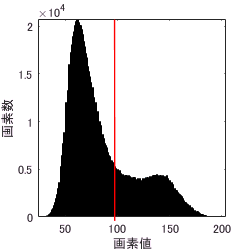

%バイナリ画像を保存する
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_07_10_binalize_calf_pictures')
imwrite(BW_B, '2018_07_10_binalize_soleus_otsu.jpg', 'jpg')
%ヒストグラムを使ってしきい値の決め方が直観的にわかるようにする
level_gray_B = graythresh(gray_B) * 255;
histogram(gray_B,256)
xlabel('画素値')
ylabel('画素数')
axis tight
annotation(gcf,'line',[0.458854166666667 0.458333333333333],...
    [0.116545265348595 0.921956295525495],'Color',[1 0 0],'LineWidth',1);
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_07_10_binalize_calf_pictures\2018_07_10_threshold_calf_otsu','png',[250,250]);

path(oldpath)